**1. Develop a matlab function that creates K samples of D-dimensional Gaussian data with arbitrary specified mean and covariance matrix**

clear all;
K = 1000;
D = 3;

test_m = [0 0 0];
test_sigma = [1 0 0; 0 1 0; 0 0 1];

m_a = [0 4 7];
m_b = [10 5 5];
m_c = [-2 -5 -5];

sigma_a = [6.5 2.1651 1.25;2.1651 5.125 2.3816;1.25 2.3816 2.375];
sigma_b = [3.0184 0.4331 -1.4481;0.4331 0.9436 -0.6456;-1.4481 -0.6456 1.288];
sigma_c = [6.8928 -1.375 3.1945;-1.375 3.3572 0.6945;3.1945 0.6945 3.75];


%% 2. Testing the function which generates gaussian distribution 


% A = generate_gdist(K,D,test_m,test_sigma);
% mean(A)
% cov(A)


test_dist = generate_gdist(K,D,test_m,test_sigma);
mean(test_dist)

ans =    -0.0536   -0.0046   -0.0206


cov(test_dist)

ans =     0.9851    0.0030   -0.0650
    0.0030    1.0163    0.0042
   -0.0650    0.0042    0.9875


In the above generated distribution, the mean and covariance are close but not exactly same as the values for which the gaussian distribution has to be generated.

**3.Discuss why, when K < infinity, the Matlab's computed covariance matrix for your Gaussian generated data will not exactly match the covariance you prescribed.**

As the 1000 sample distribution is randomly picked from the infinite points, randn() might have picked the points equally around the mean in every dimension. Even if the points are equally picked from all the directions of the mean, corelation would not be as mentioned by the covariance matrix as the selection of the points are done randomly and the distance between each point may vary from other point along the same dimension. When k=infinity ,every point in the infinite set will be picked which makes the distribution symmetric around mean with the mentioned covariance.

**4.Develop an appropriate methodology to correct for this.**

To overcome the above issue for finite set of points, we implement whitening transform which centralizes the points around origin which are statistically independent and with variance of every feature = unity.

Then, coloring transformation is applied to adjust the mean to the desired mean and tilt the distribution with the mentioned covariance.


%% 4. calling the Function which adjusts the mean, covariance and ensures that correct distribution is picked.
test_dist = transform(test_dist,test_m,test_sigma)

test_dist =     0.1851   -1.9123   -1.6627
   -1.4541   -0.5341    1.1530
    0.5155    0.3943   -2.5004
    0.1854    1.7072   -0.1469
   -0.4196   -0.2579   -1.4982
    0.7376   -0.7394   -0.7860
   -0.2306   -0.9197   -0.0309
   -1.7005   -0.2995    1.7329
   -1.6923    0.3530    0.9818
    0.6681   -1.3559    1.7412


cov(test_dist)

ans =     1.0000    0.0000   -0.0000
    0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000


mean(test_dist)

ans = 	1.0e+-16 *

    0.5729    0.1998   -0.0311


**5. Use your created function to create 1000 data samples each drawn from the three 3-dimensional Gaussian data classes A, B, and C**

A : `mean`

`     0     4     7`

`covariance `

`    6.5000    2.1651    1.2500`

`    2.1651    5.1250    2.3816`

`    1.2500    2.3816    2.3750`

A = generate_gdist(K,D,m_a,sigma_a);
A = transform(A,m_a,sigma_a)

A =     2.4006    6.3005    8.3168
   -1.2659    6.1296    7.6886
   -0.9031    3.3086    7.5313
    0.8151    7.2428    8.1745
   -0.5639    3.8256    6.1139
    3.3775    7.2420    7.7931
    3.1612    1.0970    7.0787
   -0.7483   -0.0309    4.4127
    3.3129    5.8419   10.0891
   -0.7012    4.2960    4.6678


B : `mean`

`    10     5     5`

`covariance`

`    3.0184    0.4331   -1.4481`

`    0.4331    0.9436   -0.6456`

`   -1.4481   -0.6456    1.2880`

B = generate_gdist(K,D,m_b,sigma_b);
B = transform(B,m_b,sigma_b)

B =     8.2058    5.1296    4.7971
   11.7521    6.0330    3.4634
    9.0548    5.1517    4.7478
    8.4523    3.6352    7.5080
    8.4730    4.4434    5.6808
   12.6015    6.2733    4.2413
   11.4465    5.8177    3.4778
    6.6361    5.2099    5.8777
    9.9595    3.6849    6.6871
   11.2826    4.2162    5.9450


C : mean

`    -2    -5    -5`

`covariance`

`    6.8928   -1.3750    3.1945`

`   -1.3750    3.3572    0.6945`

`    3.1945    0.6945    3.7500`

C = generate_gdist(K,D,m_c,sigma_c);
C = transform(B,m_c,sigma_c)

C =    -4.7183   -3.7273   -4.0979
    0.8808   -4.5343   -2.3850
   -3.4210   -4.2121   -4.2353
   -4.5136   -5.9497   -9.5511
   -4.4799   -4.9383   -5.9759
    2.5122   -4.3864   -4.0002
    0.2944   -4.7499   -2.3803
   -6.7983   -2.3363   -5.6458
   -2.3892   -6.9889   -8.4349
   -0.2507   -6.9913   -7.2955



figure 
scatter3(A(:,1),A(:,2),A(:,3),'r.')
hold on 
scatter3(B(:,1),B(:,2),B(:,3),'g.')
scatter3(C(:,1),C(:,2),C(:,3),'c.')
xlabel('X-axis')
ylabel('Y-axis')
zlabel('Z-axis')

title('1000 sample Distributions of A, B, C classes - Contours plotted with standard Deviation')
grid off

**6. Use matlab's ellipsoid() function to create contour intervals for Classes A, B, and C at one, two, and three standard deviations from mean of A, B,and C and also on the same plot the principal axes of each generated Gaussian contour ellipses using matlab's line() function.**

1,2,3 standard deviation contours:

[Ea,va] = plot_ellipsoids(m_a,sigma_a,[1 0 0])

Ea =    -0.7071   -0.7071    0.0000
   -0.6124    0.6124   -0.5000
   -0.3536    0.3536    0.8660


va =     9.0000         0         0
         0    4.0000         0
         0         0    1.0000


[Eb,vb] = plot_ellipsoids(m_b,sigma_b,[0 1 0])

Eb =    -0.8365    0.4387    0.3283
   -0.2241   -0.8207    0.5255
    0.5000    0.3660    0.7849


vb =     4.0000         0         0
         0    1.0000         0
         0         0    0.2500


[Ec,vc] = plot_ellipsoids(m_c,sigma_c,[0 1 1])

Ec =    -0.8536    0.1464    0.5000
    0.1465   -0.8535    0.5000
   -0.5000   -0.5000   -0.7071


vc =     9.0000         0         0
         0    3.9999         0
         0         0    1.0001


view([45,45])

Principal Axes :

princpal_axes(m_a,Ea,va)

s =     9.0000
    6.0000
    3.0000


princpal_axes(m_b,Eb,vb)

s =     6.0000
    3.0000
    1.4999


princpal_axes(m_c,Ec,vc)

s =     9.0000
    6.0000
    3.0001


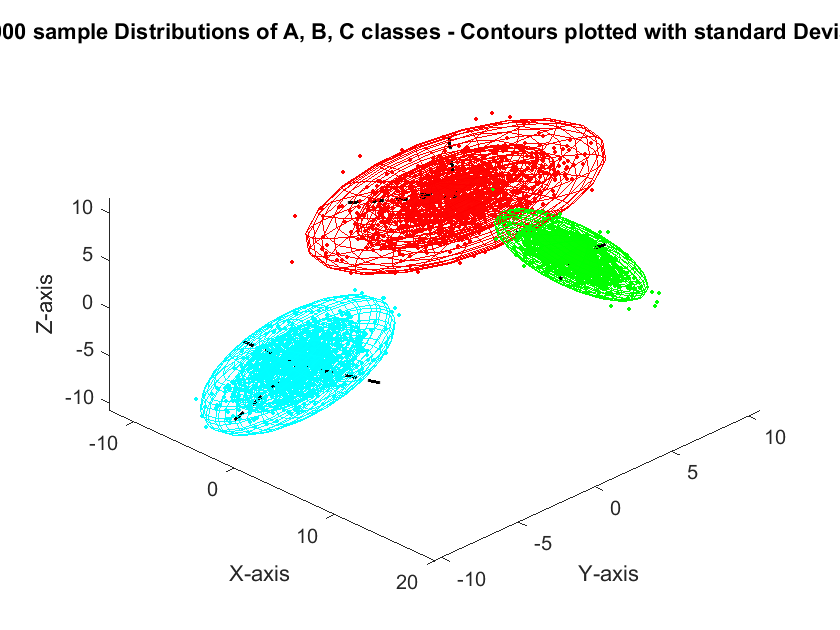


view([45 45])

function data = generate_gdist(samples,dimensions,m,sigma)
data  = randn(samples,dimensions);
[E,v] = eigs(sigma);
data = v^(1/2) * E * data.';
data = data.' + m;
end



function dist = transform(data,m,sigma)

%%whitening transformation
data = data-mean(data);
[E,v] = eigs(cov(data));
Y = E*v^(-1/2);
X = data * Y;

% X is the distribution around Origin with unit distance between points in corresponding dimensions

%cov(X)          %% identity matrix
%mean(X)         %% zero row-vector (origin)

%%coloring transformation
[E1,v1] = eigs(sigma);
Y = v1^(1/2) * X';
dist = E1 * Y;
dist = dist'+m;
end



function [E,v] =plot_ellipsoids(m,sigma,edge_color)
[E,v] = eigs(sigma);
std_ = sqrt(diag(v));
[x1,y1,z1] = ellipsoid(0,0,0,std_(1),std_(2),std_(3));
[x2,y2,z2] = ellipsoid(0,0,0,2*std_(1),2*std_(2),2*std_(3));
[x3,y3,z3] = ellipsoid(0,0,0,3*std_(1),3*std_(2),3*std_(3));


a = kron(E(:,1),x1); 
b = kron(E(:,2),y1); 
c = kron(E(:,3),z1);
d = a+b+c; 

n = size(d,2);

x1 = d(1:n,:)+m(1); 
y1 = d(n+1:2*n,:)+m(2); 
z1 = d(2*n+1:end,:)+m(3);

surf(x1,y1,z1,'FaceAlpha',0.01,'EdgeColor',edge_color);

a = kron(E(:,1),x2); 
b = kron(E(:,2),y2); 
c = kron(E(:,3),z2);
d = a+b+c;

x2 = d(1:n,:)+m(1); y2 = d(n+1:2*n,:)+m(2); z2 = d(2*n+1:end,:)+m(3);

surf(x2,y2,z2,'FaceAlpha',0.01,'EdgeColor',edge_color);

a = kron(E(:,1),x3); 
b = kron(E(:,2),y3); 
c = kron(E(:,3),z3);
d = a+b+c; 

x3 = d(1:n,:)+m(1); y3 = d(n+1:2*n,:)+m(2); z3 = d(2*n+1:end,:)+m(3);

surf(x3,y3,z3,'FaceAlpha',0.01,'EdgeColor',edge_color);
end



function [] = princpal_axes(m,E,v)
s = 3*sqrt(diag(v))
x1 = [m(1) s(1)*E(1,1)+m(1)];
y1 = [m(2) s(2)*E(2,1)+m(2)];
z1 = [m(3) s(3)*E(3,1)+m(3)];

x2 = [m(1) s(1)*E(1,2)+m(1)];
y2 = [m(2) s(2)*E(2,2)+m(2)];
z2 = [m(3) s(3)*E(3,2)+m(3)];

x3 = [m(1) s(1)*E(1,3)+m(1)];
y3 = [m(2) s(2)*E(2,3)+m(2)];
z3 = [m(3) s(3)*E(3,3)+m(3)];

line(x1,y1,z1,'LineWidth',1.5,'LineStyle','--','Color','k');
line(x2,y2,z2,'LineWidth',1.5,'LineStyle','--','Color','k');
line(x3,y3,z3,'LineWidth',1.5,'LineStyle','--','Color','k');

end

